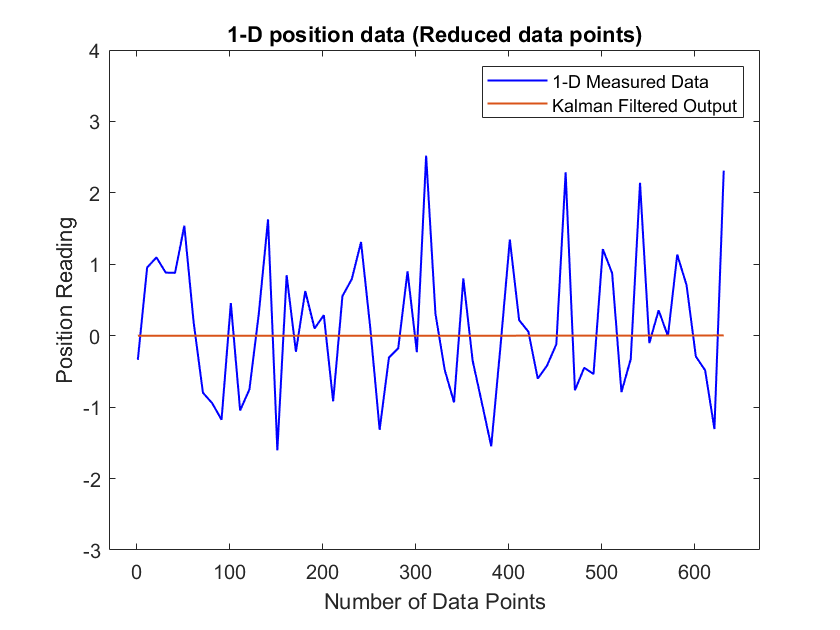

% This Program is written by Mayuresh Bhosale that depicts Kalman Filter
% applied to 1-D and 2-D data

clc
clear all
close all
%1-D Data & Plot
Adata = importdata('1D-data.txt');
xaxis = 1:height(Adata);


%Initializing
x_t = [0; 0]; %Position and Velocity Initialization
Q_t = [0 1]; %Dynamic Noise
Y_t = 0; %Measurement
% R_t = 1; %Measurement Noise
S = [1 0; 0 1]; % State Covariance Matrix
Q_var = [0 0; 0 10^(-10)]; %Dynamic noise Covariance Matrix
R_var = 10^10; %Measurement Covariance Matrix
Phi = [1 1; 0 1]; %State transition Matrix
M = [1 0]; %Observation Matrix
I = eye(2); %Identity matrix

%Equations for Kalman Filtering

for i = 1:height(Adata)
    %Predict next state
    x_tt1 = Phi*x_t;
    %Predict Next State Covariance
    S_tt1 = Phi*S*Phi'+Q_var;
    %Obtain Measurements
    Y_t = Adata(i);
    %Calculating Kalman Gain
    K_t = S_tt1*M'* inv(M*S_tt1*M' + R_var);
    %Update State
    x_t = x_tt1 + K_t*(Y_t-M*x_tt1);
    X_t(i) = x_t(1);
    %Update State Covariance
    S = (I - K_t*M)*S_tt1;
end
t1 = tiledlayout(1,1);
nexttile
%Plotting Reduced Data
plot(xaxis(1:10:639),Adata(1:10:639),'b',"LineWidth",1);
xlabel('Number of Data Points');
ylabel('Position Reading');
title('1-D position data (Reduced data points)');
hold on
plot(xaxis(1:10:639),X_t(1:10:639),"LineWidth",1);
legend('1-D Measured Data','Kalman Filtered Output')
xlim([-30,670])
ylim([-3,4])
hold off
exportgraphics(t1,'Trial_4_Graph_1.eps')

t2 = tiledlayout(1,1);

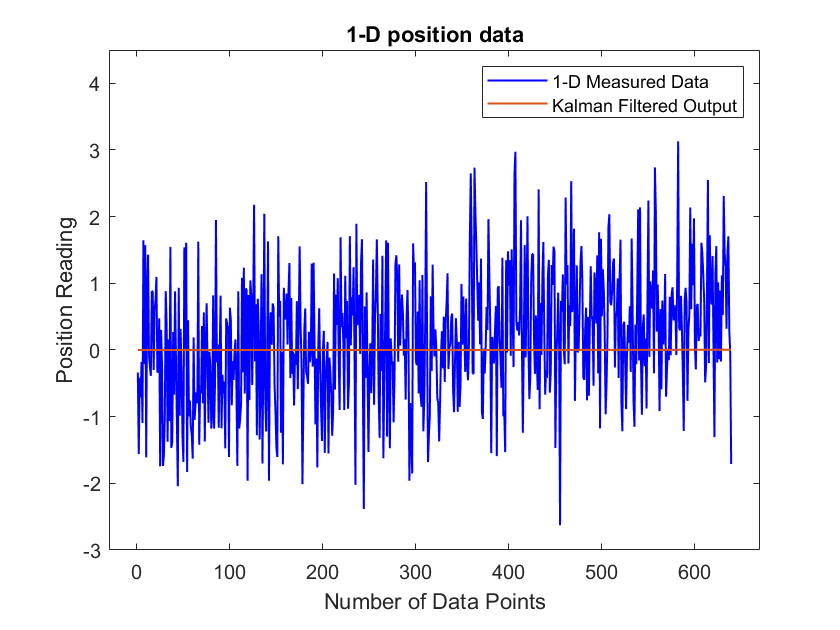

nexttile
%Plotting Reduced Data
plot(xaxis,Adata,'b',"LineWidth",1);
xlabel('Number of Data Points');
ylabel('Position Reading');
title('1-D position data');
hold on
plot(xaxis,X_t,"LineWidth",1);
legend('1-D Measured Data','Kalman Filtered Output')
xlim([-30,670])
ylim([-3,4.5])
hold off
exportgraphics(t2,'Trial_4_Graph_2.eps')

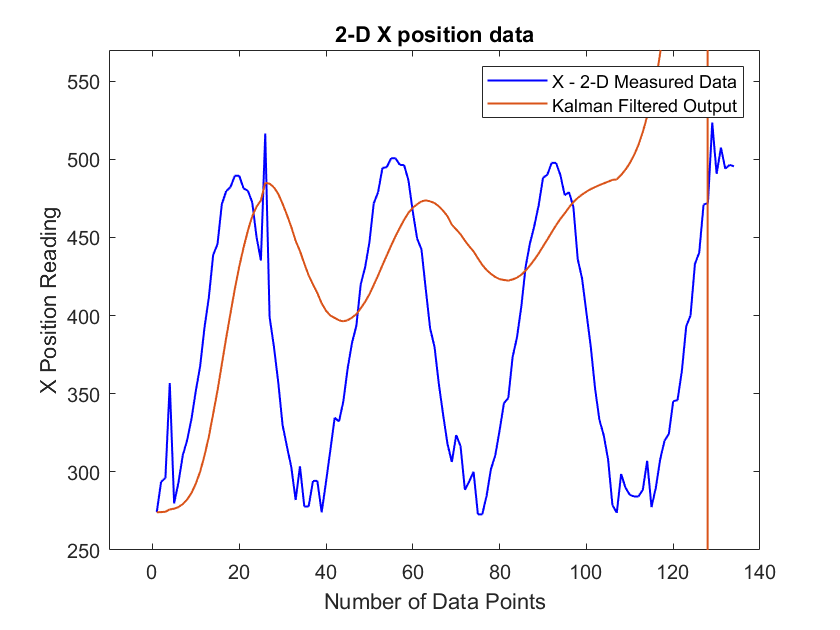

% This Program is written by Mayuresh Bhosale that depicts Kalman Filter
% applied to 1-D and 2-D data

clc
clear all
close all
%1-D Data & Plot
Adata = importdata('2D-UWB-data.txt');
xaxis = 1:height(Adata);

%Initializing
X_t = [Adata(1,1); Adata(1,2); 0; 0]; %Position and Velocity Initialization
Q_t = [0 1]; %Dynamic Noise
Y_t = [0 0]; %Measurement
% R_t = [0.01 0.0001; 
% %        0.001 0.01]; %Measurement Noise
% R_t = [1 0.1; 
%        0.1 1]; %Measurement Noise

S = [1 0 0 0;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1]; % State Covariance Matrix
Q_var = [0 0 0 0; 
         0 0 0 0; 
         0 0 0.0001 0.001; 
         0 0 0.001 0.0001]; %Dynamic noise Covariance Matrix
R_var = [1000 0.1; 
       0.1 1000]; %Measurement Covariance Matrix
Phi = [1 0 1 0; 
       0 1 0 1; 
       0 0 1 0; 
       0 0 0 1]; %State transition Matrix
M = [1 0 0 0; 
     0 1 0 0]; %Observation Matrix
I = eye(4); %Identity matrix

%Equations for Kalman Filtering

for i = 1:height(Adata)
    %Predict next state
    x_tt1 = Phi*X_t;
    %Predict Next State Covariance
    S_tt1 = Phi*S*Phi'+Q_var;
    %Obtain Measurements
    Y_t = [Adata(i,1); Adata(i,2)];
    %Calculating Kalman Gain
    K_t = S_tt1*M'* inv(M*S_tt1*M' + R_var);
    %Update State
    X_t = x_tt1 + K_t*(Y_t-M*x_tt1);
    X1(i) = X_t(1,1);
    X2(i) = X_t(2,1);
    %Update State Covariance
    S = (I - K_t*M)*S_tt1;
end

t1 = tiledlayout(1,1);
nexttile
%Plotting Reduced Data
plot(xaxis,Adata(:,1),'b',"LineWidth",1);
xlabel('Number of Data Points');
ylabel('X Position Reading');
title('2-D X position data');
hold on
plot(xaxis,X1,"LineWidth",1);
legend('X - 2-D Measured Data','Kalman Filtered Output')
xlim([-10,140])
ylim([250,570])
hold off
exportgraphics(t1,'2D_Trial_4_Graph_X.eps')

t2 = tiledlayout(1,1);

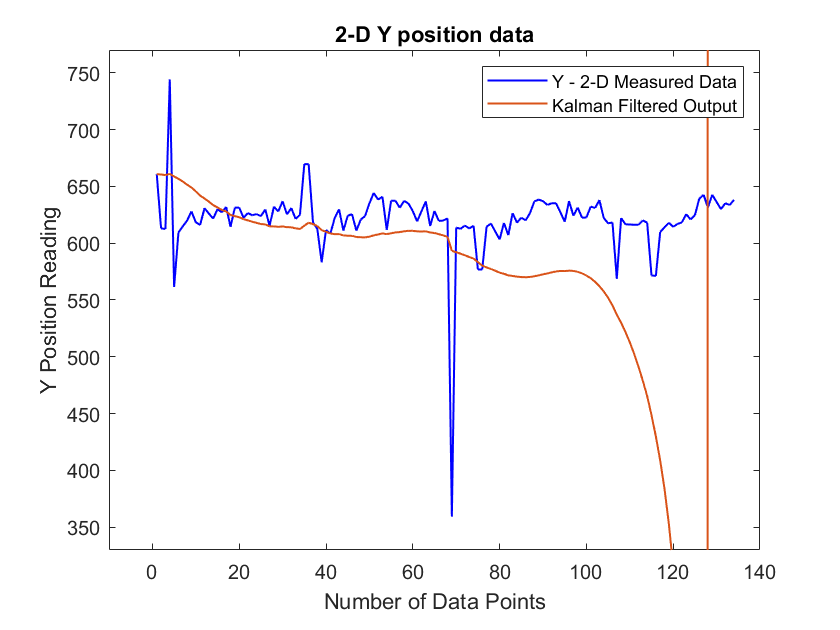

nexttile
%Plotting Reduced Data
plot(xaxis,Adata(:,2),'b',"LineWidth",1);
xlabel('Number of Data Points');
ylabel('Y Position Reading');
title('2-D Y position data');
hold on
plot(xaxis,X2,"LineWidth",1);
legend('Y - 2-D Measured Data','Kalman Filtered Output')
xlim([-10,140])
ylim([330,770])
hold off
exportgraphics(t2,'2D_Trial_4_Graph_Y.eps')